% part 1
two_d_points = [0 0; -1 2; -3 6; 1 -2; 3 -6]

two_d_points =      0     0
    -1     2
    -3     6
     1    -2
     3    -6


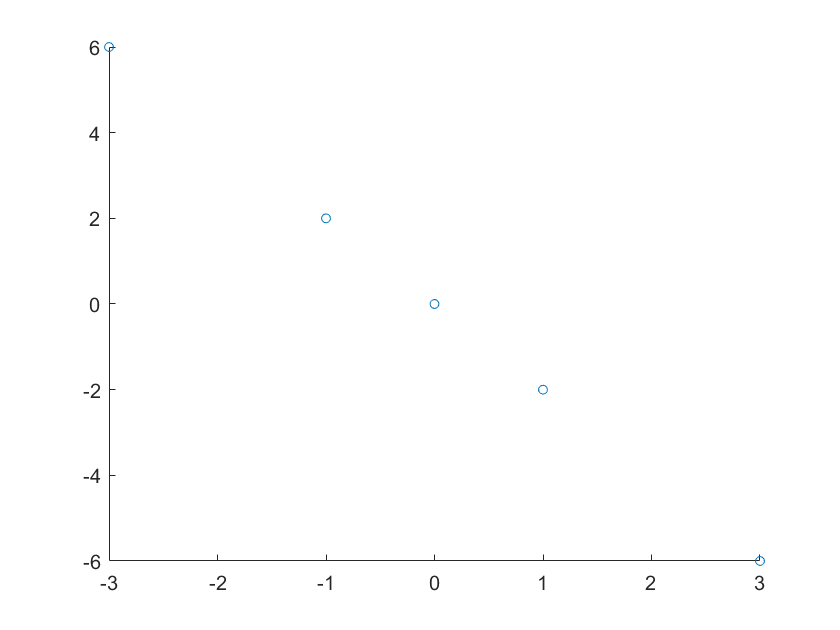


% plot the points
figure;
scatter(two_d_points(:, 1), two_d_points(:,2),20,'o'); % Scatter plot with points of size 20

load USPS.mat

mean_of_A = mean(A, 1);
centered_A = A - mean_of_A;
[U, S, V] = svd(centered_A);

p_components = [10 50 100 200];
r_error = zeros(size(p_components))

r_error =      0     0     0     0


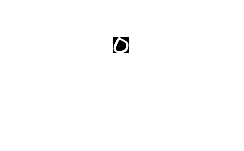


% first show the first 10 handwritten digits 
% in their original resolution
A1 = reshape(A(1,:), 16, 16);
A2 = reshape(A(2,:), 16, 16);

imshow(A1');

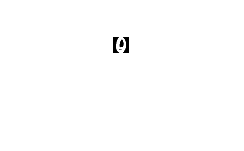

imwrite(A1','original_A1.png')
imshow(A2');

imwrite(A2','original_A2.png')

% loop through and compress and decompress
for p = 1:size(p_components,2)
    % part one implement PCA and compress image information
    compressed = (centered_A * V(:,1:p_components(p)));

    % part two show reconstructed image and compute reconstruction error
    reconstructed = compressed * V(:,1:p_components(p))' + mean_of_A;
    r_A1 = reshape(reconstructed(1,:), 16, 16);
    r_A2 = reshape(reconstructed(2,:), 16, 16);
    imwrite(r_A1',strcat('p_',string(p_components(p)),'_A1.png'));
    imwrite(r_A2',strcat('p_',string(p_components(p)),'_A2.png'));
    
    r_error(p) = norm(A - reconstructed,'fro')^2;
end

disp(r_error)

   1.0e+05 *

    1.5535    0.4102    0.1429    0.0137

